clear all % 2130-2140 0915-
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


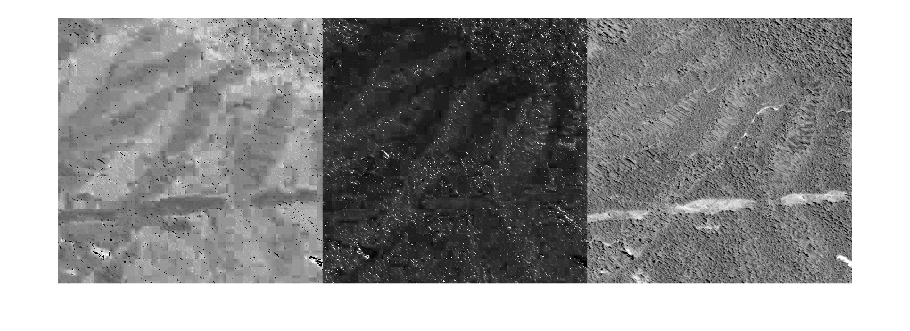

dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";

% Select image
img_2 = double(imread(img_directory + 'Hokkaido0002.tif'));
label_2 = double(imread(label_directory + 'Hokkaido0002.tif'));

% Locate red pixels edges of landslides
img = imgs(:,:,:,2);
label = labels(:,:,:,2);
img_hsv = rgb2hsv(img);
    
% Extract colour channels
R_CH = img(:,:,1); % Red CH
G_CH = img(:,:,2); % Green CH
B_CH = img(:,:,3); % Blue CH
H_CH = img_hsv(:,:,1); % Hue CH
S_CH = img_hsv(:,:,2); % Saturation CH
V_CH = img_hsv(:,:,3); % Value CH

figure;
montage([H_CH S_CH V_CH]);

%imtool(H_CH);

H_thresh = 0.25

H_thresh = 0.2500

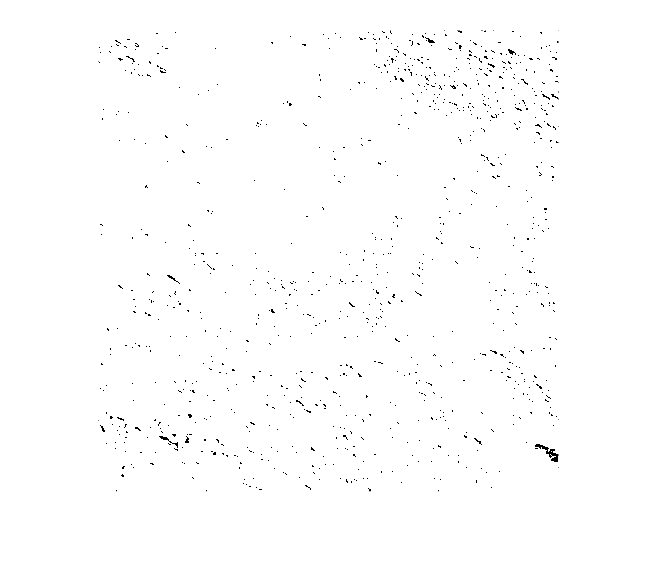

H_mask = H_CH;
H_mask = H_mask >= H_thresh;
figure;
imshow(H_mask);


% Remove small bits of mask
window_size = 100

window_size = 100

threshold = 80;
for row = 1:window_size:512-window_size+1
    for col = 1:window_size:512-window_size+1
        temp = H_mask(row:row+window_size-1, col:col+window_size-1);
        if sum(temp) < threshold
            H_mask(row:row+window_size-1, col:col+window_size-1) = 0;   
        end
    end
end
figure;
imshow(H_mask);

for i=1:1
    % Locate red pixels edges of landslides
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    img_hsv = rgb2hsv(img);
    
    % Extract colour channels
    R_CH = img(:,:,1); % Red CH
    G_CH = img(:,:,2); % Green CH
    B_CH = img(:,:,3); % Blue CH
    H_CH = img_hsv(:,:,1); % Hue CH
    S_CH = img_hsv(:,:,2); % Saturation CH
    V_CH = img_hsv(:,:,3); % Value CH
